clear all
clc
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t)

m1=4; m2=2;L=3; 

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];
g=9.81;

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;

DES=[eq1;eq2;eq3;eq4;eq7];
disp_const=[eq5;eq6];
vel_const = [];


The unknown functions (just the base functions, not derivatives) are: F1x(t),F2x(t),F3x(t),F1y(t),F2y(t),F3y(t),theta1(t),theta2(t),x1(t),x2(t),y1(t),y2(t)
Initial Conditions:
Y0/YP0:
F1x: 2.479355 F1xt:0.000000
F2x: 4.958710 F2xt:0.000000
F3x: -4.958710 F3xt:0.000000
F1y: 58.463226 F1yt:0.000000
F2y: -13.223226 F2yt:0.000000
F3y: 13.223226 F3yt:0.000000
theta1: 0.000000 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.000000 x1t:1.500000
x2: 1.060660 x2t:3.000000
y1: -1.500000 y1t:0.000000
y2: -4.060660 y2t:0.000000
Dtheta1t: 1.000000 Dtheta1tt:1.239677
Dtheta2t: 0.000000 Dtheta2tt:-5.843895
Dx1t: 1.500000 Dx1tt:1.859516
Dx2t: 3.000000 Dx2tt:-2.479355
Dy1t: 0.000000 Dy1tt:1.500000
Dy2t: 0.000000 Dy2tt:-3.198387


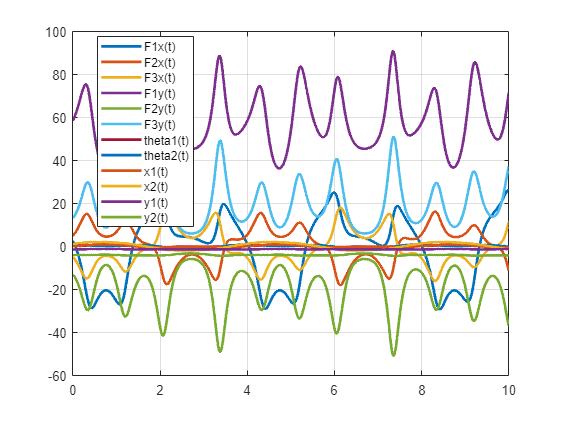


soln=mechanicsAsDAE(DES,disp_const,vel_const,[0 10],{theta1==0,theta2==pi/4,diff(theta1)==1,diff(theta2)==0});

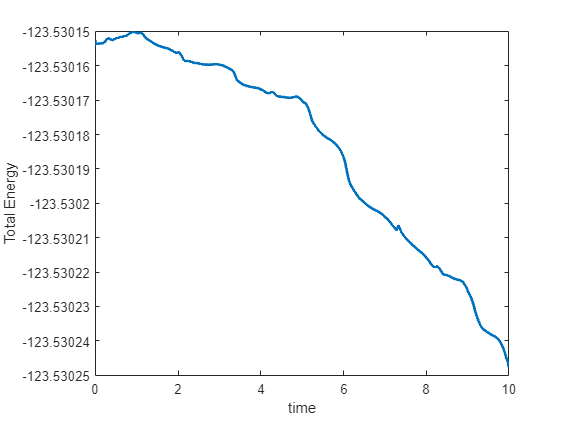

KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)...
    +1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2;
PotentialEnergy=m1*soln.y1*g+m2*soln.y2*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

[pureDEs,PPs]=analyzeSystem(DES,disp_const,vel_const,...
    [theta1,diff(theta1),theta2,diff(theta2)])

The unknown functions are:
F1x(force)
F2x(force)
F3x(force)
F1y(force)
F2y(force)
F3y(force)
theta1
theta2
x1
x2
y1
y2

Expected Number of State Variables:4


$$pureDEs = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=\frac{3\,\left(\frac{981\,\sin\left(\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right)\right)}{2}+\frac{4251\,\sin\left(\theta_{1}\left(t\right)\right)}{2}+200\,\sigma_{2}\,\sigma_{3}+150\,\sin\left(\sigma_{1}\right)\,\sigma_{4}\right)}{50\,\left(9\,\cos\left(\sigma_{1}\right)-31\right)}\\ \frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=-\frac{2943\,\sin\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-1962\,\sin\left(\theta_{2}\left(t\right)\right)+1500\,\sigma_{2}\,\sigma_{4}+225\,\sin\left(\sigma_{1}\right)\,\sigma_{3}}{225\,\cos\left(\sigma_{1}\right)-775} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right)\\ \sigma_{2}=\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$

soln=timeStepODESystem(pureDEs,[theta1,theta2],...
    [theta1==0,theta2==pi/4,diff(theta1)==1,diff(theta2)==0], ...
    [0,20],PPs);

The unknown functions (just the base functions, not derivatives) are: theta1(t),theta2(t)


Error using odearguments
When the first argument to ode23s is a function handle, the tspan argument must have at least two
elements.

Error in ode23s (line 122)
    = odearguments(odeIsFuncHandle, odeTreatAsMFile, solver_name, ode, tspan, y0, options, varargin);

Error in timeStepODES


plot(soln.t,soln.theta1,soln.t,soln.theta2,'LineWidth',2); legend({'theta1','theta2'});xlabel('Time')


KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)+...
    1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2;
PotentialEnergy=m1*soln.y1*g+m2*soln.y2*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')
